# Ch00 如何使用这套讲义

**本章目标 / Learning objectives**

1. 知道这套学习库的目录结构。 2. 学会运行 startup_learning.m 初始化路径。 3. 学会查看 MATLAB 版本、工具箱和帮助文档。 4. 建立每次学习的基本流程：运行、修改、观察、记录。

**Key terms:** workspace, current folder, command window, live script, toolbox, path

clear; clc; close all;

if exist("startup_learning", "file") == 2
    learningRoot = startup_learning();
else
    learningRoot = fileparts(fileparts(mfilename("fullpath")));
    addpath(learningRoot);
    addpath(fullfile(learningRoot, "functions"));
    addpath(fullfile(learningRoot, "data", "external_paths"));
end

## 1. 查看学习库结构

建议你先把 MATLAB 的 Current Folder 切换到学习库根目录：

你的学习库根目录，例如克隆 GitHub 仓库后的 learn-matlab 文件夹。

然后运行 startup_learning。

disp("Learning root:");
disp(learningRoot);

folderList = ["chapters", "chapters_src", "functions", "examples", "data", "tests", "docs", "projects"];
for k = 1:numel(folderList)
    folderPath = fullfile(learningRoot, folderList(k));
    fusionlearn.utils.checkPathExists(folderPath, folderList(k));
end

## 2. 查看 MATLAB 版本和工具箱

version 返回 MATLAB 版本。 ver 返回已安装产品列表。

matlabVersionText = version;
products = ver;

fprintf("MATLAB version: %s\n", matlabVersionText);
fprintf("Number of installed products: %d\n", numel(products));

if ~isempty(products)
    firstProducts = products(1:min(8, numel(products)));
    disp(struct2table(firstProducts));
end

局部运行核心看**节（Section）****和****选区**：

- **运行当前节**：光标停在要运行的节内，按 `Ctrl + Enter`（最常用，只运行当前蓝色竖线框内的代码）。

- **运行当前节并跳到下一节**：按 `Ctrl + Shift + Enter`。

- **仅运行选中的几行代码**：用鼠标高亮选中需要运行的代码，按 `F9`。

- **分节方法**：在代码行输入 `%%` 加空格，或点击顶部工具栏的 **“分节符” (Section Break)** 按钮。

先按 Alt + Enter（或点击顶部工具栏的 “文本” 按钮）将当前行切为**富文本模式**，然后即可像 Markdown 或 Word 一样排版：

- **标题与字号**：顶部工具栏在 **“实时编辑器”** 选项卡下，点击 **“普通”** 下拉菜单，选择 **标题 1 / 标题 2 / 标题 3**（对应 Markdown 的 #、##、###，自动改变字号）。

- **加粗**：选中文字按 Ctrl + B（Mac 上为 Cmd + B）。

- **斜体**：选中文字按 Ctrl + I。

- **行内代码**：选中文字按 Ctrl + Shift + D（或工具栏上的等宽字体按钮）。

- **插入公式**：按 Ctrl + E（可直接输入 LaTeX 代码）

*提示：输入完文本后，按 *Alt + Enter* 可快速切回写代码模式。*

## 3. help 和 doc

help 适合快速看函数用法。 doc 适合打开完整官方文档。

下面的命令不会自动打开 doc 页面，避免打断运行；你可以手动在命令行输入：

help plot doc plot

helpText = help("plot");
disp(extractBefore(string(helpText), min(strlength(string(helpText)), 600)));

## 4. 一个最小可运行例子

这是你学习每章时的基本动作：运行一段代码，改参数，再看图形变化。

MATLAB 采用面向对象与属性-值对（Name-Value Pairs）机制。每个窗口都是一个图形对象（Figure Object），系统为你预设了默认属性，通过  `'属性名', 属性值`  的配对形式，在创建时覆盖默认值。

**常用属性分类：**

外观与文字

- `'Name'`：标题栏自定义名称，如 `'Name', '数据分析图'`

- `'NumberTitle'`：是否显示默认序号 `'off'` / `'on'`（常设为 `'off'`，隐藏前面的 "Figure 1:"）

- `'Color'`：窗口底色，如 `'Color', 'w'`（白色）或 `'Color', [0.9 0.9 0.9]`（RGB 灰）

尺寸与位置

- `'Position'`：设置 `[左, 下, 宽, 高]`，如 `[100, 100, 800, 600]`（像素）

- `'WindowState'`：快速设定状态 `'maximized'`（最大化）、`'minimized'`（最小化）、`'fullscreen'`（全屏）

显示与行为

- `'Visible'`：是否立即可见 `'on'` / `'off'`（常用于后台批量绘图导出，防闪烁）,设置为 off 可用以下命令行形式打开，my_figure.fig改为对应的fig文件名：fig = openfig('my_figure.fig', 'visible');

- `'MenuBar'`：是否保留顶部菜单 `'none'` / `'figure'`

- `'ToolBar'`：是否保留工具栏 `'none'` / `'auto'`

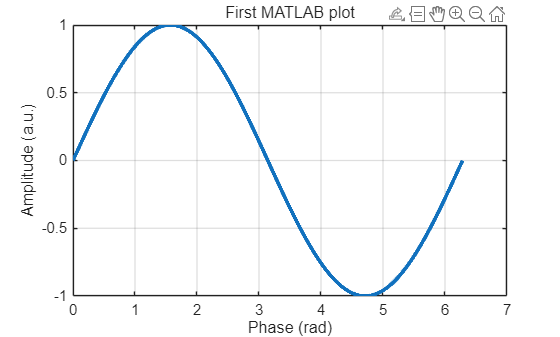

t = linspace(0, 2*pi, 4000);
y = sin(t);

figure("Color", "w");%字母对应颜色英文原名
% r红色red
% g绿色green
% b蓝色blue
% c青色cyan
% m洋红magenta
% y黄色yellow
% k黑色black（避免与 blue 冲突）
% w白色white
plot(t, y, "LineWidth", 3);%先x轴，再y轴，Linewith为拟合曲线宽度，算样式调节
xlabel("Phase (rad)");
ylabel("Amplitude (a.u.)");
title("First MATLAB plot");
grid on;

fusionlearn.plot.applyResearchStyle(gca);

plot(t, y, "LineWidth", 1.5);以 t 为横轴、y 为纵轴绘制二维折线图，并将线宽设为 1.5 磅（比默认粗，更清晰）。

xlabel("Phase (rad)");命名 X 轴标签为相位（弧度单位 rad）。

ylabel("Amplitude (a.u.)");命名 Y 轴标签为振幅（a.u. 即 arbitrary units，任意/归一化单位）。

title("First MATLAB plot");为图表添加顶部标题。

grid on;开启坐标轴网格线，方便对照数值。

fusionlearn.plot.applyResearchStyle(gca);核心定制函数：

gca（**G**et **C**urrent **A**xes）获取当前坐标轴对象句柄。

调用自定义工具包（命名空间 fusionlearn.plot）中的 applyResearchStyle 静态方法，对当前图表一键应用科研论文级样式（通常内部封装了字号统一、字体切换为 Arial/Times、加粗坐标边框、刻度线朝向、去除多余留白等规范设置）。

## 5. 学习方式建议

推荐节奏：

1. 先完整运行本章。 2. 修改参数，比如把 sin 改成 cos，把线宽改成 2。 3. 出错时不要马上删代码，先读报错信息。 4. 把错误原因写进学习日志。 5. 最后完成练习，再看参考答案。

## 6. 常见错误 / Common mistakes

错误 1：Current Folder 没切到学习库根目录。 结果：MATLAB 找不到 startup_learning 或 fusionlearn 函数。

错误 2：把大实验数据复制进学习库。 结果：目录混乱，后续 Git 管理困难。

错误 3：看到报错就重启 MATLAB。 更好的方式：先看第一行错误、文件名和行号。

## 7. 练习

练习 1：运行 startup_learning，确认输出根目录。 练习 2：用 version 查看 MATLAB 版本。 练习 3：用 ver 查看是否下载了 Signal Processing Toolbox工具。 练习 4：画 cos(t) 曲线。 练习 5：把曲线标题改成英文。

## 8. 参考答案

rootFromStartup = startup_learning();
assert(isfolder(rootFromStartup));

disp(version);

v_answer = ver;
productNames = string({v_answer.Name});
hasSignalToolbox = any(contains(productNames, "Signal Processing Toolbox"));
fprintf("Signal Processing Toolbox installed: %d\n", hasSignalToolbox);

t_answer = linspace(0, 2*pi, 400);
y_answer = cos(t_answer);
figure("Color", "w");
plot(t_answer, y_answer, "LineWidth", 1.5);
xlabel("Phase (rad)");
ylabel("Amplitude (a.u.)");
title("Cosine wave example");
grid on;
fusionlearn.plot.applyResearchStyle(gca);

## 9. 本章检查表

[ √ ] 我能运行 startup_learning。 [ √ ] 我知道 Current Folder 是什么。 [ √ ] 我能查看 MATLAB 版本和工具箱。 [ √ ] 我知道 help 和 doc 的区别。 [ √ ] 我能运行并修改一个简单绘图例子。